## The three models share the same R0

syms beta_m beta_h theta_m theta_h mu_m gamma_h mu_h R_0
pars=[beta_m beta_h theta_m theta_h mu_m gamma_h mu_h];
R_0=beta_m*beta_h*theta_h*theta_m/((theta_m+mu_m)*(gamma_h+mu_h)*(theta_h+mu_h)*(mu_m))

$$R\_0 = \frac{\beta_{h}\,\beta_{m}\,\theta_{h}\,\theta_{m}}{\mu_{m}\,\left(\gamma_{h}+\mu_{h}\right)\,\left(\mu_{h}+\theta_{h}\right)\,\left(\mu_{m}+\theta_{m}\right)}$$

[T,~]=gsua_dpmat(R_0,pars,1,'R_0')

Introduce ranges in the following order: 


$$ans = \left(\begin{array}{ccccccc} \beta_{m} & \beta_{h} & \theta_{m} & \theta_{h} & \mu_{m} & \gamma_{h} & \mu_{h} \end{array}\right)$$

T = 7×2 table
               Range     Nominal
               ______    _______

    beta_m     0    0       0   
    beta_h     0    0       0   
    theta_m    0    0       0   
    theta_h    0    0       0   
    mu_m       0    0       0   
    gamma_h    0    0       0   
    mu_h       0    0       0   


load Results7.mat
common=intersect(T7.Properties.RowNames,T.Properties.RowNames)

common = 6×1 cell array
    {'beta_h' }
    {'beta_m' }
    {'gamma_h'}
    {'mu_m'   }
    {'theta_h'}
    {'theta_m'}


T{'mu_h','Range'}=[4e-4,4e-4];
T{'mu_h','Nominal'}=4e-4;
T{common,'Range'}=T7{common,'Range'};
%T.Nominal=[];
T{common,'T7'}=T7{common,'Estlsqc'}(:,1:476);

load Results8_complete.mat
T{common,'T8'}=T8{common,'Estlsqc'}(:,1:158);

load Results10_complete.mat
T{common,'T10'}=T10{common,'Estlsqc'}(:,1:136);

T.T7(end,:)=repmat(4e-4,1,476);
T.T8(end,:)=repmat(4e-4,1,158);
T.T10(end,:)=repmat(4e-4,1,136);

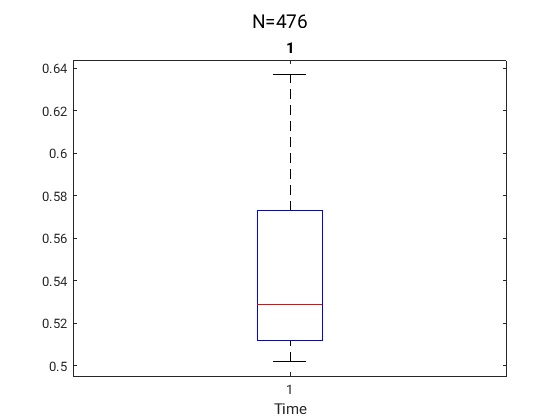

clf
gsua_eval(T.T7,T);

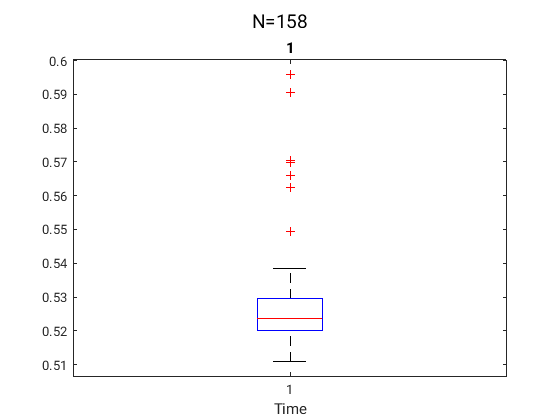

clf
gsua_eval(T.T8,T);

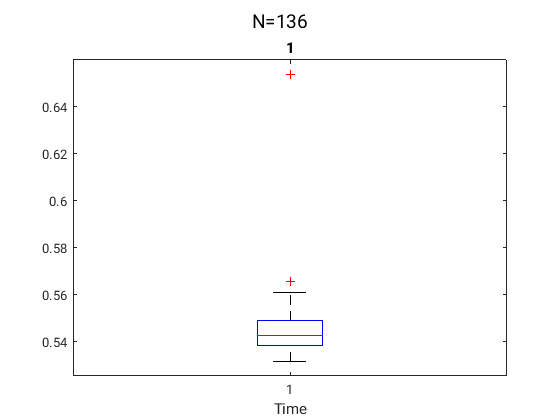

clf
gsua_eval(T.T10,T);

% load Basic_model_7.mat
% T.T7_old=T7{common,'Estlsqc'};

## Extracting necessary values

a=symvar(R_0)

$$a = \left(\begin{array}{ccccccc} \beta_{h} & \beta_{m} & \gamma_{h} & \mu_{h} & \mu_{m} & \theta_{h} & \theta_{m} \end{array}\right)$$

for i=1:length(a)
    ce{i}=char(a(i));
end
R2=subs(R_0,a([2:7]),[T{ce([2:7]),'T10'}(:,1)]')

$$R2 = \frac{410280716448664318685107617636962811499799624361705472000000000\,\beta_{h}}{1817068461204252086597276806881810643587692053613070006721207539}$$

assume(a(1)>=0)
param=vpa(solve(R2==1.1,a(1)))

$$param = 4.8717261796406428910690826693734$$

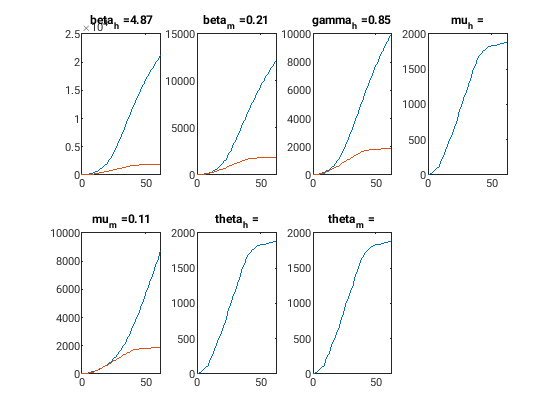

load Results10_complete.mat
y=r0(R_0,T(:,'T10'),1.1,T10,'T10',xdata,ydata2);